This livescript will introduce basic principles of Homer3 and guide you through the implementation of a simple pipeline without the Homer3 GUI, in a tutorial style. You will learn how to:

## Loading SNIRF Data Files

We will load the files from the [Shared Near Infrared Spectroscopy Format](https://fnirs.org/resources/software/snirf/) (SNIRF), which was designed to facilitate sharing and analysing NIRS data. A detailed description about the format can be found [here](https://github.com/fNIRS/snirf/blob/master/snirf_specification.md#snirf-data-format-summary). We can select one or more measurement files in the dialog box. Here, we chose to load all three measurement files in our experiment into *data_nirs.*

clear all; close all;

% Select data file to process
p = fileparts(which('simple_pipeline.m'));
while 1
    [fname, pname] = uigetfile([p, '/../SampleData/', '*.snirf'], 'Select snirf file(s)', 'MultiSelect', 'on');
    if fname == 0
        q = menu('You have not selected a data file. Click OK to continue or CANCEL to quit', ...
            {'OK','CANCEL'});
        if q==2
            return
        end
    else
        break;
    end
end

% Load raw intensity signals and metadata into data_nirs 
if iscell(fname) 
    data_nirs = cell(1, numel(fname));
    for fi = 1:numel(fname)
        data_nirs{fi} = SnirfClass([pname, fname{fi}]); 
    end
else
    data_nirs = {SnirfClass([pname, fname])}; 
end


%
% We will now proceed to work with just one measurement data, which we will 
% call _acquired. _
acquired = data_nirs{1};

% The _acquired _Snirf data object contains both raw intensity signals for each 
% wavelength and metadata, such as stimuli information, probes source/detector 
% geometry, measurement date and time, etc. We will now work on the intensity 
% signals and, for that, we save a copy of it in the _intensity_nirs_ variable. 
% It's important to note that just assigning "acquired.data" data structure to 
% _intensity_nirs _ variable will only point to the data in _acquired _data object. 
% This means that any further modifications that we do on _intensity_nirs_ will 
% also be done on the data contained in _acquired. _To prevent this from happening, 
% we create a copy of it as follows:
intensity_nirs = acquired.data.copy; % raw intensity signals

## Convert Intensities to Optical Densities

We will proceed to convert these signals into optical density (OD) signals. These signals represent the attenuation of the transmitted light $(I_0)$in tissue, as measured by the receivers $(I$), for each wavelength. 


$$OD(t, \lambda)$$
 
$$=-log_{10}$$

$$\left(\frac{I(t,\lambda}{I_0(t,\lambda)}\right)}$$


The computation in Homer3 is as follows:

dod = hmrR_Intensity2OD(intensity_nirs);

## Detect Motion Artifacts

Parts of the data can be contaminated by artefacts, which could be systemic artefacts (e.g. heartbeat,respiration), or be caused by extrinsic factors (e.g. subject movement) ([Tachtsidis&Scholkmann, 2016](https://www.spiedigitallibrary.org/journals/neurophotonics/volume-3/issue-3/031405/False-positives-and-false-negatives-in-functional-near-infrared-spectroscopy/10.1117/1.NPh.3.3.031405.full?SSO=1)). Both these types of artefacts need to be handled separately. In this tutorial, we focus on the latter.

Motion artefacts detection is often done by visual inspection of non-physiological data patterns or automated analysis. Homer3 provides the hmrR_MotionArtifactByChannel function, which detects outliers using standard deviation and amplitude thresholds. 

We will set these thresholds to be 50 and 5, respectively, and choose a 1 second sliding window in which the channel-wise amplitude and standard deviation will be evaluated to detect outliers. If any active data channel exhibits a signal change greater than STDEVthresh or AMPthresh, then a segment of data around that time point is marked as a motion artifact. The channel-wise motion artifacts are recorded in the output matrix *tIncAutoCh, _where 1s represent motion-free data and 0s represent motion contaminated data. Time points in the recording where at least one channel has a motion artifact are indicated in a similar manner by the vector _tIncAuto*.

% PARAMETERS:
tMotion = 0.5;
tMask = 1.0;
STDEVthresh = 10;
AMPthresh = 1.00;
[tIncAuto, tIncAutoCh] = hmrR_MotionArtifactByChannel(dod, acquired.probe, [], [], [], ...
    tMotion, tMask, STDEVthresh, AMPthresh);

## Correct Motion Artifacts

Having already detected the motion artifacts in our data, we will now proceed to artefact handling. Artefact handling can be done in two ways: either, the data is removed from further analysis, or it is interpolated e.g. using cubic spline interpolation algorithm ([Scholkmann et al., 2010](https://pubmed.ncbi.nlm.nih.gov/20308772/)). We opted for the latter, which is imlpemented in homer as follows:

dodMC = hmrR_MotionCorrectSpline(dod.copy, [], tIncAutoCh, 0.99);       % Motion corrected ODs


%
% We now plot the resulting motion-corrected signals.
t = dod.time;
y = dod.dataTimeSeries;
yMC = dodMC.dataTimeSeries;

% Plot position parameters:   
px      = .01;
py      = .30;
sx      = .30;
sy      = .40;
xstep   = .15;

% Channels to plot 
channels = 1:size(y, 2);
figure('menubar','none', 'numbertitle','off', 'name','OD Before and After Motion Correction', ...
    'units','normalized','position',[px, py, sx, sy]);
px = px + xstep;

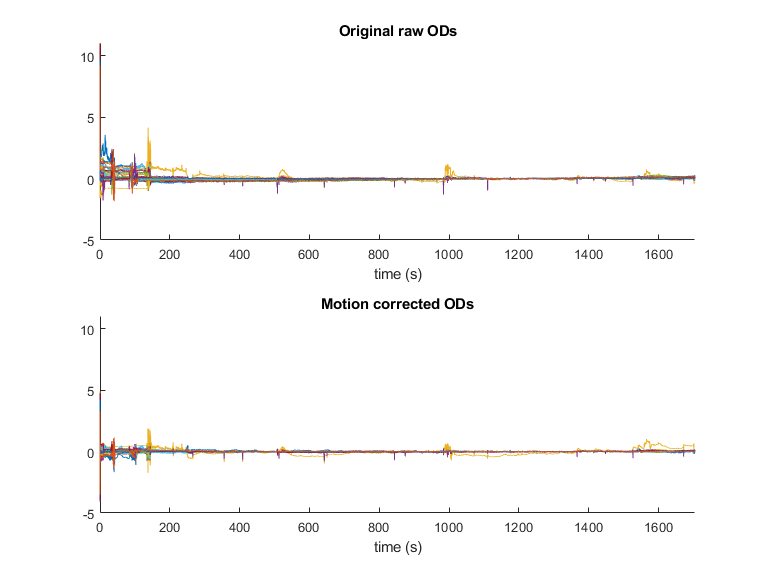

ax1 = subplot(211); hold on
for iCh = 1:length(channels)
    plot(t, detrend(y(:, iCh)));
    xlabel('time (s)')
end
title('Original raw ODs')
xlim([t(1), t(end)]);

ax2 = subplot(212); hold on
for iCh = 1:length(channels)
    plot(t, detrend(yMC(:, iCh)));
    xlabel('time (s)')
end
title('Motion corrected ODs')
xlim([t(1), t(end)]);

linkaxes([ax1, ax2])

pause(1);

## Convert Optical Densities to Hemoglobin Concentration Changes

Once our data has been corrected for motion, we compute the concentration changes in O2Hb and HHb by means of the Modified Lambert-Beer Law [(Delpy et al., 1988)](https://iopscience.iop.org/article/10.1088/0031-9155/33/12/008). This conversion requires the user to insert ppf (partial pathlength factor) values corresponding to each wavelength. These are age and wavelength specific. Here we use 6.06.

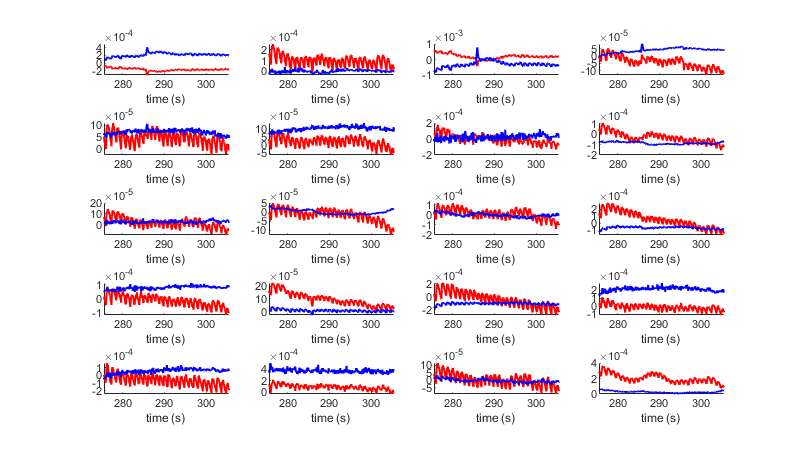

dhb  = hmrR_OD2Conc(dodMC, acquired.probe, [1,1]);


%
% Data visualization:

% Extract plot data from output of last function 
t = dhb.time;
y = dhb.GetDataTimeSeries('reshape');

% fs = 1/diff(dhb.time(1:2)); % sampling frequency
tstart = acquired.stim(1).data(1,1);
tend = tstart + 30;

% Hb type - {1 -> HbO,  2 -> HbR,  3 -> HbT}
hbType   = [1, 2];

% channels to plot 
subplotDims = [5,4];                            % Subplot dimensions in terms of rows and columns
nSubplots = subplotDims(1) * subplotDims(2);    % number of subplots = number of subplot rows X number of subplot columns
nChannels = size(y,3);
if nSubplots > nChannels
    channels = 1:nChannels;
else
    channels = 1:nSubplots;
end
color_map = {'r', 'b', 'green'};
figure('menubar','none', 'numbertitle','off', 'name','Hb0/HbR Concentration Time Course', ...
    'units','normalized','position',[px, py, sx*1.3, sy]);
px = px + xstep;

for iHb = 1:length(hbType)
    axes_array = [];
    for iCh = channels
        axes_array = [axes_array, subplot(5,4,iCh)]; hold on
        plot(t, detrend(y(:, hbType(iHb), channels(iCh))),...
            color_map{iHb}, 'LineWidth', 1.5);
        xlabel('time (s)')
        xlim([tstart, tend]);
        hold on
    end
    pause(1)
end
linkaxes(axes_array, 'x')

## Bandpass Filtering

In a common analysis pipeline, fNIRS data is filtered such that the frequency of the hemodynamic response remains and frequencies of other signal components are filtered out. Although there are different opinions on the best filter cutoffs for estimating the hemodynamic response, most researchers filter out frequencies above 0.1 Hz ([Pinti et al., 2018](https://www.frontiersin.org/articles/10.3389/fnhum.2018.00505/full)) in the healthy adult population. We will additionally filter frequencies bellow 0.01 Hz, and we will do so bu means of a bandpass filter.

dhbFilt = hmrR_BandpassFilt(dhb, 0.01, 0.5);

## Average Over Trials

Averaging of data is usually first done across trials per condition, and, if available, over different sessions (also called runs), and then over subjects or per subject groups. In this tutorial, we have analysed data from a single subject performing the same task in multiple sessions, and have focused in just one of these sessions.

We are interested in performing a block average over trials belonging to our fingertapping task. To do so, we first have a look at the stimulus information contained out _acquired _Snirf data structure.

for ii = 1:length(acquired.stim)
    fprintf('Event type:  %s\n', acquired.stim(ii).name)
end

Event type:  Fingertapping
Event type:  Instructions
Event type:  Rest period




% To perform the block average, the recorded data is segmented into those time 
% periods of experimental interest. The segmented period includes a few seconds 
% of time before the task onset and few seconds of time after the task offset. 
% We select stim(1), corresponding to the fingertapping task, and choose a prestimulus 
% and poststimulus time of 5 and 30 seconds, respectively. The short period before 
% the onset of the experimental task is usually used as a baseline. This allows 
% making inference between a baseline period (e.g. rest) and a task period (e.g. 
% finger tapping). 
% 
% Having set all of these parameters, we then proceed to average over trials 
% per channel as follows:
tPre = -5;
tPost = 30;
dhbAvg = hmrR_BlockAvg(dhbFilt, acquired.stim(1), [tPre, tPost]);

% Extract plot data from output of last function 
tAvg = dhbAvg.time;
yAvg = dhbAvg.GetDataTimeSeries('reshape');
channels = 1:nChannels;
hbPlotNames = {'HbO ', 'HbR ', 'HbT '};
hbType   = [1, 2, 3];

## Plot Final Results in a Graph

Displaying NIRS-data is typically done by plotting both the average changes of oxy- and deoxyhemoglobin in time. Here, we plot the resulting HbO, HbR and HbT averaging signals

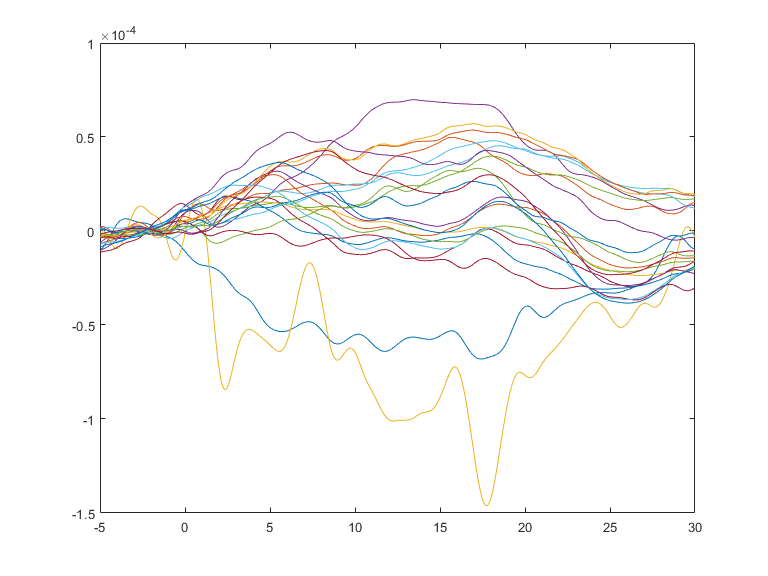

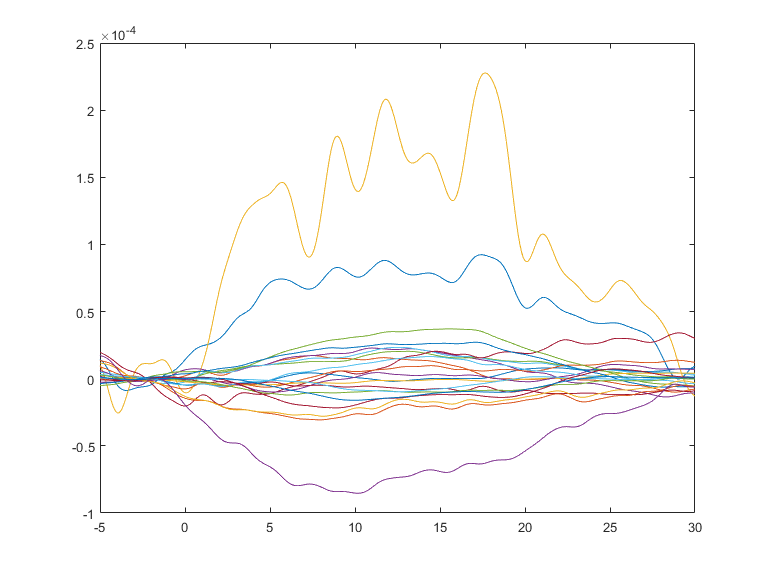

for iHb = 1:length(hbType)
    figure('menubar','none', 'numbertitle','off', 'name',[hbPlotNames{iHb}, 'Concentration Block Average'], ...
        'units','normalized','position',[px, py, sx, sy]);
    px = px + xstep;
    for iCh = channels
        plot(tAvg, yAvg(:, hbType(iHb), channels(iCh)));
        hold on;
    end
    xlim([min(tAvg), max(tAvg)]);
    hold off;
    pause(1)
end

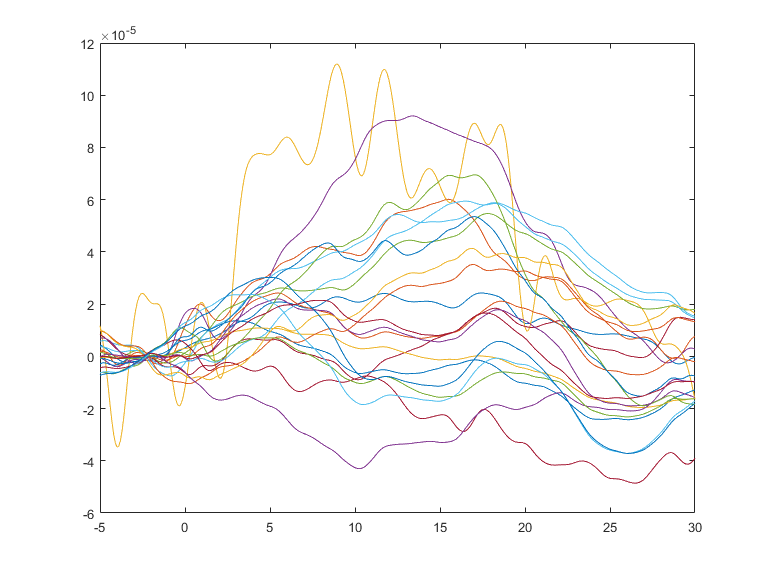

xlim([min(tAvg), max(tAvg)]);
hold off;